clc
clear
close all

% cd(fileparts(which(mfilename)))

restoredefaultpath
addpath(genpath("C:/Users/dougo/source/repos/tracking/tracker_component_library_5.3/"))
Constants;

dbstop if error

% Doug Carlson (doug.o.carlson@gmail.com), 2026-05-24 17:24

traj_obj = Tracker.Trajectory()

traj_obj =   Trajectory with properties:

            T: 1
           v0: 20
         pos0: [3×1 double]
     leg_dirs: ["N"    "S"    "N"]
    leg_times: [50 50 50]
    turn_accs: [1 -1]
           Ns: 277
            s: [7×277 double]
         mode: [0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 0 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 … ] (1×277 double)
            t: [0 1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20 21 22 23 24 25 26 27 28 29 30 31 32 33 34 35 36 37 38 39 40 41 42 43 44 45 46 47 48 49 50 51 52 53 54 55 56 57 58 59 60 61 62 63 64 65 66 67 68 69 70 71 72 73 74 75 … ] (1×277 double)
     leg_angs: [0 180]


s = traj_obj.s

s = 1.0e+03 *

         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    

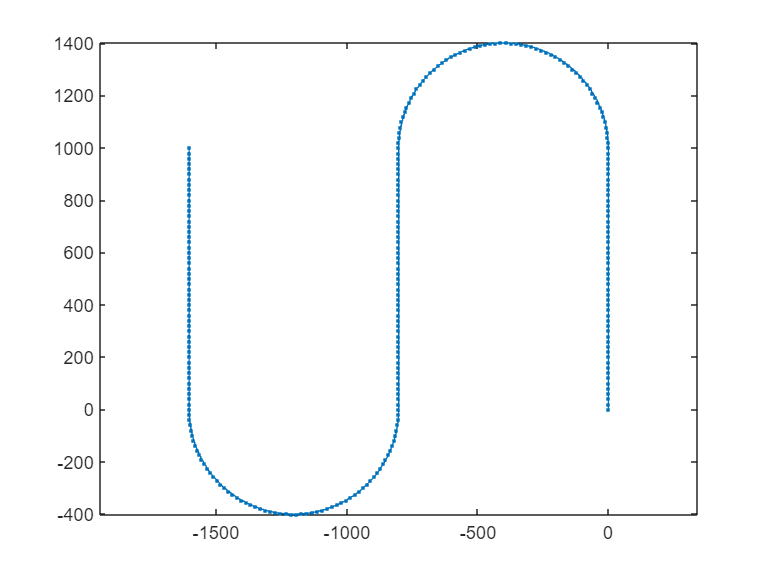

pos = s(1:3,:);

figure
plot(pos(1,:), pos(2,:), '.-')
axis equal

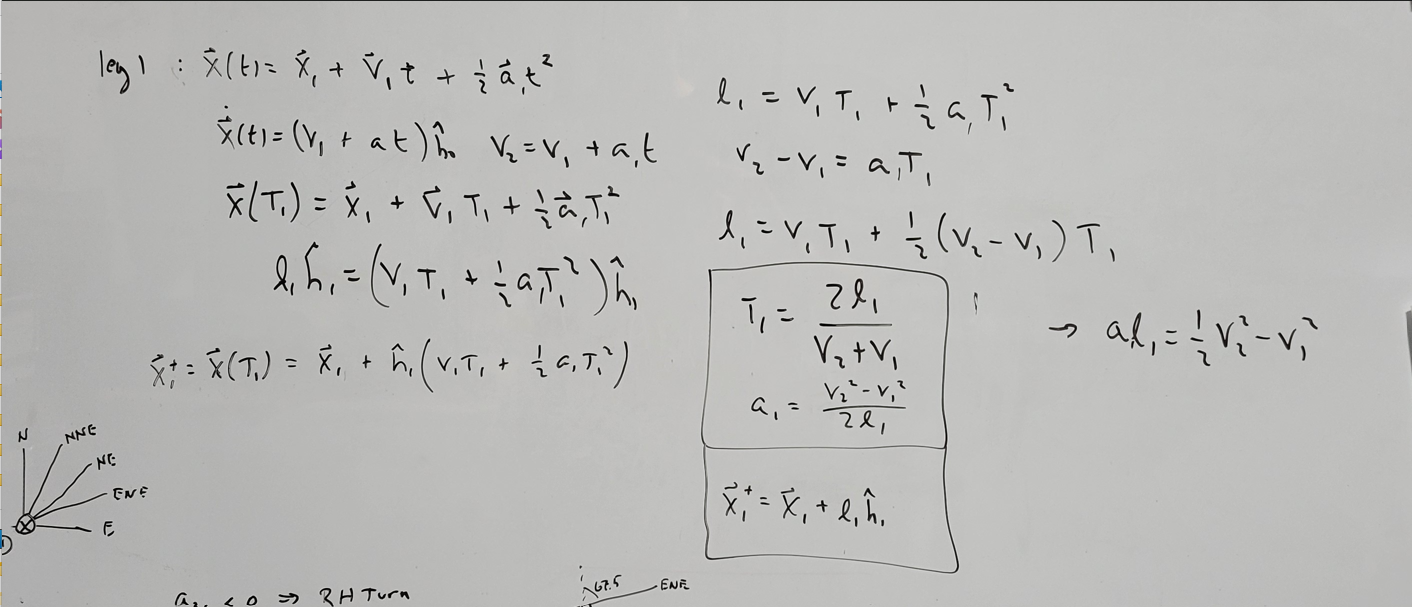

%% Compass directions and angles in True North CS
compass_dir = ["N","NNE","NE","ENE","E","ESE","SE","SSE", ...
    "S","SSW","SW","WSW","W","WNW","NW","NNW"];
compass_ang = (0:22.5:359);
T = 0.1;                    % INPUT: revisit time for interpolation afterwards
pos1 = [ 0; 0; 0];          % INPUT: inital position NED
%vel0 = [ 0; 0; 0];          % INPUT: initial velocity NED
leg_dirs = ["N","S","N"];   % INPUT: leg directions of compass rose
leg_dsts = [50,50,50];      % INPUT: time spent on each leg
leg_spds = [ 5,10, 5];      % INPUT: time spent on each leg
turn_accs = [10,-10];       % INPUT: turn acceleration, in mps, between legs

num_leg = numel(leg_dirs);
ang = zeros(1,num_leg);
for kL = 1:num_leg
    ang(kL) = compass_ang(matches(compass_dir, leg_dirs(kL)));
end
del_phi = diff(ang);

v1 = leg_spds(1);
l1 = leg_dsts(1);
v2 = leg_spds(2);
t1 = 2*l1/(v2+v1);
a1 = (v2^2 - v1^2)/(2*l1);
h1 = [cosd(ang(1)); sind(ang(1)); 0];
pos1p = pos1 + h1*l1

pos1p =     50
     0
     0
